dydx = @(x, y) y^2 + 1;
yo = 0;

xo = 0;
xf = 1;

dx = 0.1;
x = xo:dx:xf;
y = zeros(1, length(x));

% apply euler's method
y(1) = yo;
for i = 1:length(x)-1
    y(i+1) = y(i) + dydx(x(i), y(i)) * dx;
end

% apply midpoint method
y_mid = RK2(dydx, xo, xf, yo, dx, 1);

% apply Heun method
y_heun = RK2(dydx, xo, xf, yo, dx, 1/2);

% apply Ralston method
y_ralston = RK2(dydx, xo, xf, yo, dx, 2/3);

% apply RK4 
y_rk4 = RK4(dydx, xo, xf, yo, dx);

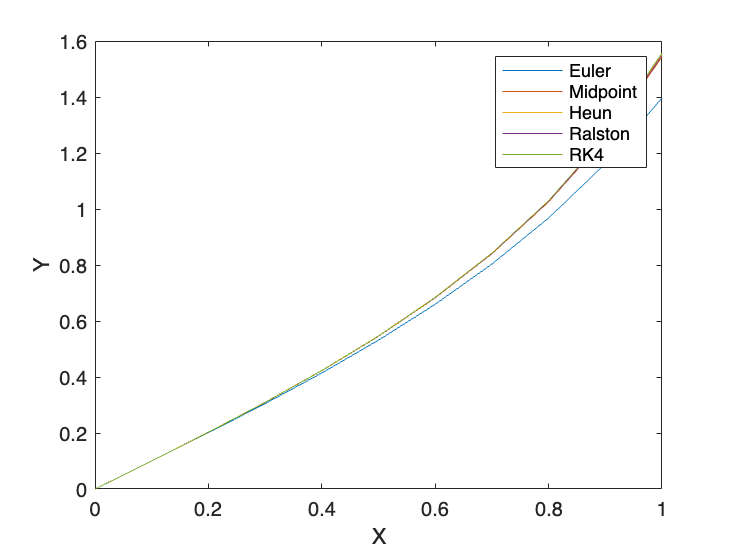

plot(x, y); hold on;
plot(x, y_mid);
plot(x, y_heun);
plot(x, y_ralston);
plot(x, y_rk4);
legend('Euler','Midpoint','Heun','Ralston','RK4');
xlabel('X');
ylabel('Y');